% Load variables
square_wave_filtered_anti_aliasing = load("C:\yizhar\square_wave_filtered_anti_aliasing.mat");

Error using load
Unable to find file or directory 'C:\yizhar\square_wave_filtered_anti_aliasing.mat'.

signal = square_wave_filtered_anti_aliasing.signal;
clear square_wave_filtered_anti_aliasing;

% Display results
signal


x = signal
upper = ceil(0.01 *length(x))

plot(x(1:50))

N = length(x);
fs = 1/N;
fc = 3200;
X_f = fft(x);
X_f_shifted = fftshift(X_f);

axis = [-N/2+1:N/2] /N * fc;

plot(axis,abs(X_f_shifted ))
title("square wave reconst. - WITH anti aliasing")
xlabel("f[Hz]")
ylabel("amplitude[V]")

% Load variables
vocal_recording_6400hz_anti_aliasing_3200hz_reconstructed = load("C:\yizhar\part4\vocal_recording_6400hz_anti_aliasing_3200hz_reconstructed.mat");
reconstexcel32 = vocal_recording_6400hz_anti_aliasing_3200hz_reconstructed.reconstexcel3;
clear vocal_recording_6400hz_anti_aliasing_3200hz_reconstructed;

% Display results
reconstexcel32

reconstexcel32 = 17636×2 table
    SamplesPlot0    AmplitudeVPlot0
    ____________    _______________

          0           -0.0060565   
          1            -0.006707   
          2            -0.004105   
          3           -0.0057313   
          4           -0.0037798   
          5            -0.004105   
          6           -0.0034545   
          7           -0.0021535   
          8           -0.0034545   
          9           -0.0018282   
         10           -0.0031293   
         11           -0.0021535   
         12           -0.0024787   
         13            -0.002804   
         14            -0.004105   
         15            -0.002804   


signal2

signal2 =    -0.0061   -0.0067   -0.0041   -0.0057   -0.0038   -0.0041   -0.0035   -0.0022   -0.0035   -0.0018   -0.0031   -0.0022   -0.0025   -0.0028   -0.0041   -0.0028   -0.0048   -0.0035   -0.0035   -0.0031   -0.0015   -0.0044   -0.0044   -0.0041   -0.0035   -0.0044   -0.0041   -0.0022   -0.0009   -0.0015   -0.0012   -0.0015   -0.0012   -0.0012   -0.0015   -0.0025   -0.0025   -0.0035   -0.0041   -0.0044   -0.0041   -0.0038   -0.0051   -0.0041   -0.0031   -0.0035   -0.0031   -0.0028   -0.0054   -0.0051


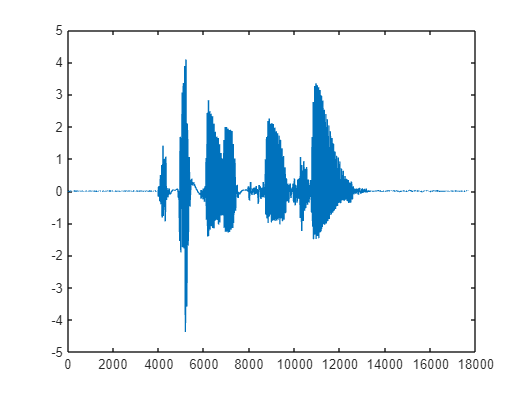


plot(signal2)


% 1. Define your sampling frequency (in Hz)
% Replace 8000 with the actual sampling rate of your speech signal
fs = 8000; 

% 2. Play the signal
% Replace 'your_array' with the name of your MATLAB variable
soundsc(signal2, fs);

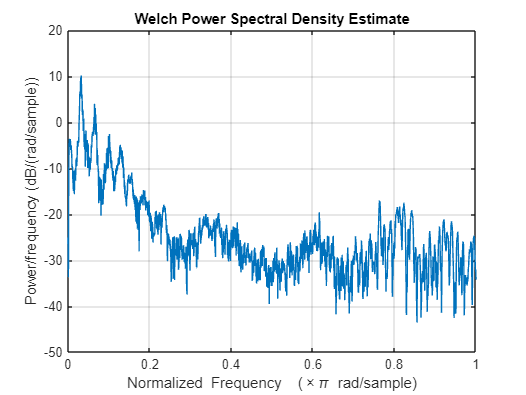

pwelch(signal2)